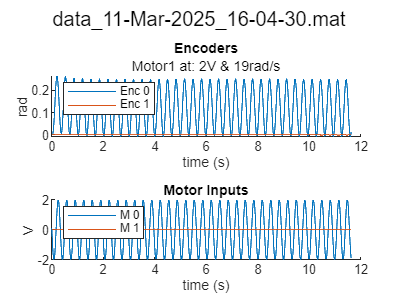

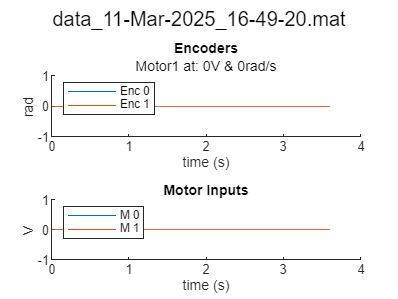

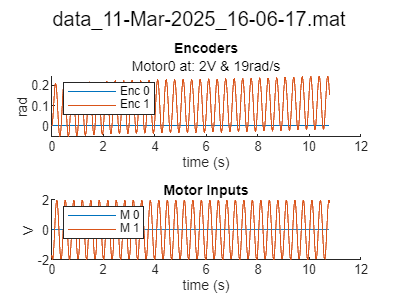

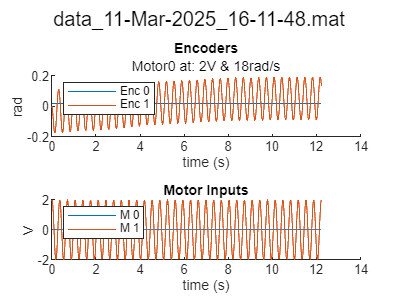

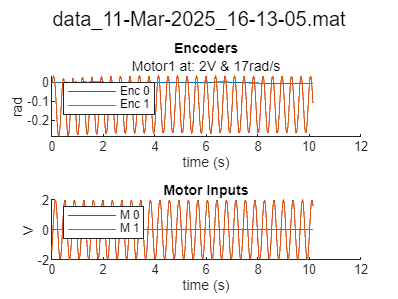

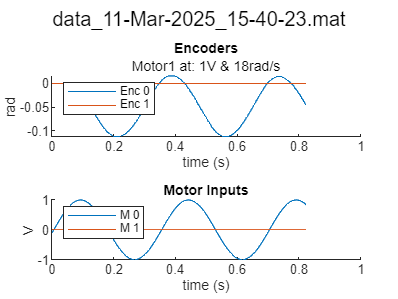

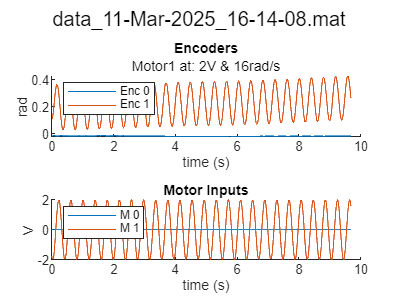

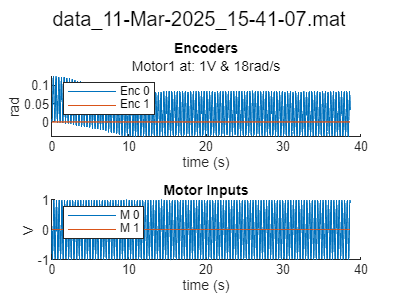

filelist =["data_11-Mar-2025_14-37-46.mat"  "data_11-Mar-2025_16-04-30.mat"  "data_11-Mar-2025_16-49-20.mat"  "data_11-Mar-2025_18-31-38.mat"   "data_11-Mar-2025_14-41-45.mat"  "data_11-Mar-2025_16-06-17.mat"  "data_11-Mar-2025_18-02-55.mat"  "data_11-Mar-2025_18-34-32.mat" "data_11-Mar-2025_15-16-40.mat"  "data_11-Mar-2025_16-11-48.mat"  "data_11-Mar-2025_18-09-05.mat"  "data_11-Mar-2025_18-38-31.mat" "data_11-Mar-2025_15-19-03.mat"  "data_11-Mar-2025_16-13-05.mat"  "data_11-Mar-2025_18-19-48.mat"  "data_11-Mar-2025_18-40-21.mat" "data_11-Mar-2025_15-40-23.mat"  "data_11-Mar-2025_16-14-08.mat"  "data_11-Mar-2025_18-21-25.mat"  "data_11-Mar-2025_18-42-37.mat" "data_11-Mar-2025_15-41-07.mat"  "data_11-Mar-2025_16-15-13.mat"  "data_11-Mar-2025_18-23-27.mat"  "data_11-Mar-2025_18-43-54.mat" "data_11-Mar-2025_15-52-28.mat"  "data_11-Mar-2025_16-16-28.mat"  "data_11-Mar-2025_18-24-00.mat"  "data_11-Mar-2025_18-45-12.mat" "data_11-Mar-2025_15-54-11.mat"  "data_11-Mar-2025_16-17-45.mat"  "data_11-Mar-2025_18-25-32.mat"  "data_11-Mar-2025_18-47-03.mat" "data_11-Mar-2025_15-59-13.mat"  "data_11-Mar-2025_16-19-12.mat"  "data_11-Mar-2025_18-26-22.mat"  "data_11-Mar-2025_18-49-24.mat" "data_11-Mar-2025_16-01-46.mat"  "data_11-Mar-2025_16-22-06.mat"  "data_11-Mar-2025_18-28-35.mat" "data_11-Mar-2025_16-03-02.mat"  "data_11-Mar-2025_16-46-42.mat"  "data_11-Mar-2025_18-29-53.mat" ];

filetitle = "trash/lab2_"+string(datetime(now, 'ConvertFrom', 'datenum','Format','yyyy-MM-dd HH+mm+ss'));

properId = [];
for n_exp = 1:(size(filelist,2))
    if n_exp == 31  %corrupted file?
        continue
    end
    load("lab2/data/"+filelist(n_exp),"data");
   
    res = lab2SmartPlot(data,filelist(n_exp));
    if res
        f = gcf;
        properId(end+1) = n_exp;
        % exportgraphics(f,filetitle+".pdf",'Append',true);
    end
end



goodId = [2
3
6
10
14
17
18
21
22
25
26
29
30
33
34
37
38
40
41]'

goodId =      2     3     6    10    14    17    18    21    22    25    26    29    30    33    34    37    38    40    41
